% function [PlanX,PlanY,PlanTheta,idx,PreviewX,PreviewY,PreviewTheta,numTraj,ref_curvature,ref_theta,lateral_error,lateral_error_rate,heading_error,heading_error_rate] ...
%     = FrenetTrajectory(A0,A1,A2,A3,Veh_Speed,YawRate,PreView_T,AyDtLimit,Min_Plan_Dis,axEgo,kapEgo)
%% 生成轨迹
Px =single([1.5 2 2.5 2.7 3 3.3 3.6 4 4.4 4.8 5.3 5.8 6.4 7.1 7.8 8.6 9.5 10.4 11.4]); %Py_Fac后期去掉，增加一个轨迹筛选条件，每个车速下最小规划距离
TarEgoAx = zeros(1,length(Px));   %初始化矩阵
Veh_Speed = 15;
axEgo = 0.5;
TarEgoV = ones(1,length(Px)) .* Veh_Speed;  %计算未来行驶车速
A0 = 3.5;A1=0.0007;A2=0.00007;A3=-3*(10)^-9;
kapEgo = 2.*A2;
if Veh_Speed>single(1)
    Px = Veh_Speed*Px;    %纵向距离 l 
end 
% Px = 30;
Py = A3*(Px.^3) + A2*(Px.^2) + A1*(Px.^1) + A0;  

x = single(zeros(11,1));
y = single(zeros(11,1));
Vx = single(zeros(11,1));
Vy = single(zeros(11,1));
Ax = single(zeros(11,1));
Ay = single(zeros(11,1));
AyDt = single(zeros(11,1));
Pt = single(zeros(1,1));     %规划时间
for i = 1:length(Py)
    Pt = 1.05*sqrt(Px(i)^2 + Py(i)^2)/max(1,0.5*(TarEgoV(i) + Veh_Speed));
    t_Vego = max(Veh_Speed,1);
    t0 = single(0);
    tn = Pt;
    T = [t0^5,t0^4,t0^3,t0^2,t0,1;...
        5*t0^4,4*t0^3,3*t0^2,2*t0,1,0;...
        20*t0^3,12*t0^2,6*t0,2,0,0;...
        tn^5,tn^4,tn^3,tn^2,tn,1;...
        5*tn^4,4*tn^3,3*tn^2,2*tn,1,0;...
        20*tn^3,12*tn^2,6*tn,2,0,0];
    Vn = TarEgoV(i);
    An = TarEgoAx(i);
    kP =  3*A3*(Px(i).^2) + 2*A2*Px(i) + A1;
    
    Kap = 6*A3*(Px(i))+2*A2;
    Arcf = (Veh_Speed^2)*Kap;
    Ayn = Arcf/sqrt(1 + kP^2);
    Axn = Arcf*kP/sqrt(1 + kP^2);
    
    Vxn = Vn/sqrt(1 + kP^2);
    Vyn = Vn*kP/sqrt(1 + kP^2);
    MaX = [0;t_Vego;axEgo;Px(i);Vxn;Axn];
    MaY = [0;0;(Veh_Speed^2)*kapEgo;Py(i);Vyn;Ayn];
    A = T\MaX;
    B = T\MaY;
    
    a5 = A(1); % 纵向轨迹系数
    a4 = A(2);
    a3 = A(3);
    a2 = A(4);
    a1 = A(5);
    a0 = A(6);
    
    b5 = B(1); % 横向轨迹系数
    b4 = B(2);
    b3 = B(3);
    b2 = B(4);
    b1 = B(5);
    b0 = B(6);
    preLineValid = true;
    for j=1:11
        t = (j-1)*tn/10;
        x(j) = a5*t^5 + a4*t^4 + a3*t^3 + a2*t^2 + a1*t + a0;
        Vx(j) = 5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1;
        Ax(j) = 20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2;
        y(j) = b5*t^5 + b4*t^4 + b3*t^3 + b2*t^2 + b1*t + b0;
        Vy(j) = 5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1;
        Ay(j) = 20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2;
        AyDt(j) = 60*b5*t^2 + 24*b4*t + 6*b3;
        if abs(AyDt(j))>20
            preLineValid = false;
            break;
        end     
    end
    if abs(sqrt(x(11)^2+y(11)^2)) < 60      %规划的距离最小不能小于设定的阈值
       preLineValid = false; 
    end
    if preLineValid
        break;
    end
end
NumTarpoints = 40;       %轨迹点的个数
y = y.*single(-1)

y = 11×1 single 列向量
         0
   -0.0328
   -0.2144
   -0.5974
   -1.1586
   -1.8246
   -2.4964
   -3.0751
   -3.4870
   -3.7089


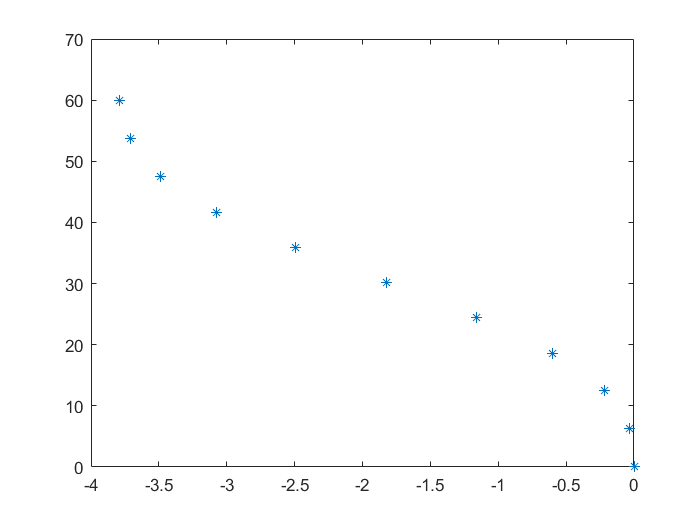

figure
plot(y',x','*')

objSpline = Spline2D(y,x)
s = single(linspace(0,objSpline.s(end),NumTarpoints))
TargetPoints = single(zeros(length(s),6))
for i = single(1):single(1):length(s)
    [ix,iy] = objSpline.calc_position(s(i))
    TargetPoints(i,1) = ix
    TargetPoints(i,2) = iy
    TargetPoints(i,3) = objSpline.calc_yaw(s(i))
    TargetPoints(i,4) = objSpline.calc_curvature(s(i))
    TargetPoints(i,5) = objSpline.calc_curvatureDerivative(s(i))
    TargetPoints(i,6) = s(i)
end
traj = single(zeros(NumTarpoints,6))
t= single(zeros(NumTarpoints,1))
costs = single(zeros(1,1))
globalTrajectory = repmat(struct('Trajectory',traj,'Times',t,'costs',costs), 1, 1)
globalTrajectory(1).Trajectory = TargetPoints
globalTrajectory(1).Times = t

numTraj  = i;%借用numTraj输出时间点索引号
%%
% [s,d]→[x, y, theta, kappa, dkappa]
PlanX= globalTrajectory(1).Trajectory(1:NumTarpoints,2);
PlanY= globalTrajectory(1).Trajectory(1:NumTarpoints,1);
PlanTheta = globalTrajectory(1).Trajectory(1:NumTarpoints,3);
[matrix_state,ref_curvature,ref_theta,idx] = Calc_State_Error(Veh_Speed,YawRate,globalTrajectory,PreView_T,NumTarpoints);
PreviewX = globalTrajectory(1).Trajectory(idx,2);
PreviewY = globalTrajectory(1).Trajectory(idx,1);
PreviewTheta = globalTrajectory(1).Trajectory(idx,3);
% lateral_error = single(zeros(1,1));lateral_error_rate = single(zeros(1,1));heading_error = single(zeros(1,1));heading_error_rate = single(zeros(1,1));
lateral_error = matrix_state(1,1);
lateral_error_rate = matrix_state(2,1);
heading_error = matrix_state(3,1);
heading_error_rate = matrix_state(4,1);


